# Nedkøling af brine

clc; clear all;

brine = importdata("NiceBrineData.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");


ind = 10;

brine_Tefordamp = find(brine.textdata(1,2:end) == "Temperaturen efter fordamper")

brine_Tefordamp = 6

brine_Tffordamp = find(brine.textdata(1,2:end) == "Temperatur efter EPV")

brine_Tffordamp = 9

brine_Tbrine = find(brine.textdata(1,2:end) == "Brinetemperatur")

brine_Tbrine = 4


brine_Tffordamp = brine.data(ind:end-ind, brine_Tffordamp);
brine_Tefordamp = brine.data(ind:end-ind, brine_Tefordamp);
brine_Tbrine = brine.data(ind:end-ind, brine_Tbrine);


ind_plot = find(max(brine_Tbrine) == brine_Tbrine)

ind_plot = 110


xs = length(brine_Tffordamp(ind:end))*2*0.142/60

xs = 33.6635

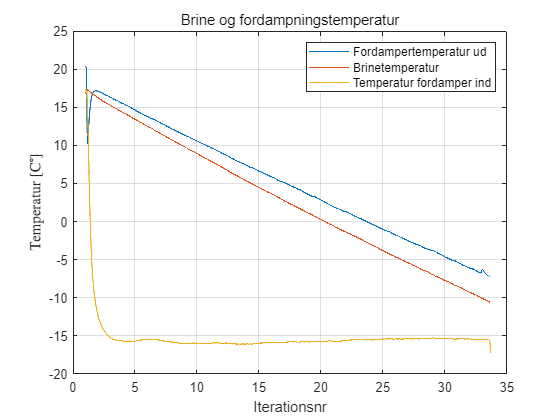


xlin = linspace(1,xs,length(brine_Tffordamp(ind_plot:end)));

figure

plot(xlin, brine_Tefordamp(ind_plot:end))
hold on
plot(xlin, brine_Tbrine(ind_plot:end))
plot(xlin, brine_Tffordamp(ind_plot:end))
hold off


title("Brine og fordampningstemperatur","FontWeight","normal")
grid("on")
legend("Fordampertemperatur ud","Brinetemperatur","Temperatur fordamper ind","location","northeast")

xlabel("Tid i [min]")
ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

## Phi

R = 2.023e-5 + 0.00391 + 7.676e-5;

phi = -(brine_Tffordamp(ind_plot:end) - brine_Tbrine(ind_plot:end))/R;


phimin = 1249.36;

min(brine_Tbrine(ind_plot:end))

ans = -10.6185

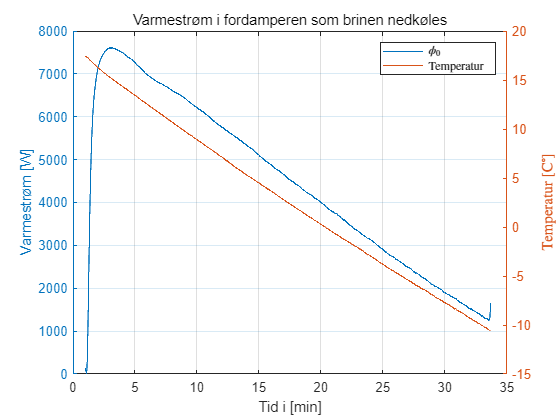


figure

yyaxis left
plot(xlin, phi)
ylabel("Varmestrøm [W]")

yyaxis right
plot(xlin, brine_Tbrine(ind_plot:end))
ylabel("Temperatur $[\mathrm{C}^\circ]$","Interpreter","latex")

title("Varmestrøm i fordamperen som brinen nedkøles","FontWeight","normal")
grid("on")
xlabel("Tid i [min]")


legend("$\phi_\mathrm{0}$","Temperatur","Interpreter","latex")

## Tryk

brine_lavtryk = find(brine.textdata(1,2:end) == "Tryk lav")

brine_lavtryk = 13

brine_hojtryk = find(brine.textdata(1,2:end) == "Tryk høj")

brine_hojtryk = 12

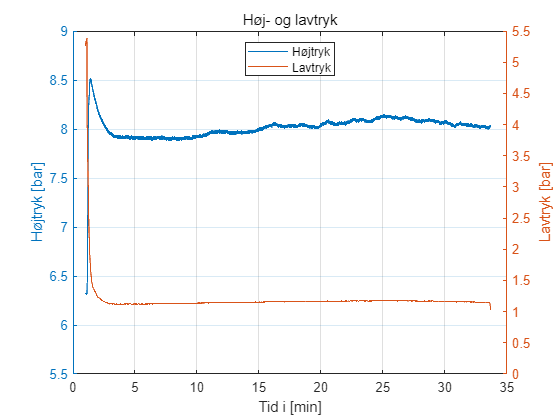


brine_lavtryk = brine.data(ind_plot:end-19, brine_lavtryk) + 1;
brine_hojtryk = brine.data(ind_plot:end-19, brine_hojtryk) + 1;


figure

yyaxis left
plot(xlin, brine_hojtryk)
ylabel("Højtryk [bar]")
ylim([5.5,9])

yyaxis right
plot(xlin, brine_lavtryk)
ylabel("Lavtryk [bar]")

ylim([0,5.5])

grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk","FontWeight","normal")
xlabel("Tid i [min]")